%clear all;
%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\2022_12_21_10_26_10.txt';
%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\2022_12_21_11_12_18.txt';
hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\wade_scans\2023_01_18_15_29_16_Wade_65mm\2023_01_18_15_17_28.txt';
%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2023_01_18_11_20_02_Jonas_70mm\2023_01_18_11_11_12.txt';

% hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_19_11_14_14_24_best_Jonas_20230118_60mm\2023_01_19_11_04_55.txt';
% hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_15_53_40_24_best_Jonas_20230118_65mm\2023_01_18_15_44_48.txt';
% hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_11_20_02_24_best_Jonas_20230118_70mm\2023_01_18_11_11_12.txt';
% hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_36_33_24_best_Jonas_20230118_75mm\2023_01_18_14_27_34.txt';
% hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_47_38_24_best_Jonas_20230118_80mm\2023_01_18_14_38_39.txt';


[hexa_string_all, hexa_string] = deal([]);
file = fileread(hexa_file_name);
hexa_string_all(1,:) = strfind(file,"X: ");
hexa_string_all(2,:) = strfind(file,", Y");
hexa_string_all(3,:) = strfind(file,"Y: ");
hexa_string_all(4,:) = strfind(file,", Z");
hexa_string_all(5,:) = strfind(file,"Z: ");
hexa_string_all(6,:) = strfind(file,", U");
hexa_string_all(7,:) = strfind(file,"U: ");
hexa_string_all(8,:) = strfind(file,", V");
hexa_string_all(9,:) = strfind(file,"V: ");
hexa_string_all(10,:) = strfind(file,", W");
hexa_string_all(11,:) = strfind(file,"W: ");
for i=1:size(hexa_string_all,1)
    hexa_string(i,:) = hexa_string_all(i,2:2:end);
end
hexa_string(12,:) = strfind(file,", T");
 
for j=1:size(hexa_string,2)
    for i=1:size(hexa_string,1)/2
        hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
    end
end
hexa_pos(1,:) = hexa_pos(1,:)*1e3;
hexa_pos(2,:) = hexa_pos(2,:)*1e3;
hexa_pos(3,:) = hexa_pos(3,:)*1e3;
hexa_pos(4,:) = hexa_pos(4,:);
hexa_pos(5,:) = hexa_pos(5,:);
 
%sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\download\';
%sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\download\';
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\wade_scans\2023_01_18_15_29_16_Wade_65mm\download\';
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2023_01_18_11_20_02_Jonas_70mm\download\';
% 
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_19_11_14_14_24_best_Jonas_20230118_60mm\download\';
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_15_53_40_24_best_Jonas_20230118_65mm\download\';
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_11_20_02_24_best_Jonas_20230118_70mm\download\';
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_36_33_24_best_Jonas_20230118_75mm\download\';
% sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\24_best_Jonas_20230118\2023_01_18_14_47_38_24_best_Jonas_20230118_80mm\download\';


[sparseQ, sparseN, sparseD] = deal([]);
sli_files = dir([sli_file_path '*.unk']);
for i=1:length(sli_files)
    [h,sli(i,:),m] = readAscImage([sli_file_path sli_files(i).name]);  
    
    sparse = [sli(i,:).sliData.Q(sli(i,:).sliData.sliID ~= 255, :)/1e3, sli(i,:).sliData.sliID(sli(i,:).sliData.sliID ~= 255, :)];
    N_s = sli(i,:).sliHeader.planeN;
    D_s = sli(i,:).sliHeader.planeD/1e3;
    
    sparseQ = [sparseQ; [sparse, i*ones(size(sparse, 1), 1)]];
    sparseN = [sparseN; [N_s, i*ones(size(N_s, 1), 1)]];
    sparseD = [sparseD; [D_s, i*ones(size(D_s, 1), 1)]];
end
hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end) ;


%Cam rotation
best_angle_x = 18; %18.27;
best_angle_y = 0; %-0.38;
best_angle_z = 0; 0.2700;
pivot_point_ = 190*10^3; %um
c2x_y = 23;        %mm
c2x_y = 19.0365; % 18.9053;
x2c_z = 22997*1e-3; %mm
%x2c_z = 27.6692; % 27.7592;   
desired_distance = 30*10^3; %um
%desired_distance = 0;
 
x_ray_pos = zeros(3,length(sli_files));
x_ray_pos(3,:) = pivot_point_;
for i=1:length(sli_files)
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    x_ray_pos(:,i) = R_hex * x_ray_pos(:,i);
    x_ray_pos(:,i) = x_ray_pos(:,i) + hexa_pos(1:3,i);
end



% Rotate and translate to "sensor frame"
for i=1:size(sli,1)
    temp = sli(i).sliData.Q'; 
    temp(4,:) = 1;
    sli_data_rot{i}.Q = temp;
    %sli_data_cen{i}.cen = sli(i).sliData.cen;
    T = [0 c2x_y (pivot_point_-desired_distance-x2c_z)]';
    %T = [0 c2x_y pivot_point-x2c_z]';
    R = createRotationMatrix(best_angle_z,best_angle_y,best_angle_x);
    P = [R T];
    sli_data_rot{i}.Q = P*sli_data_rot{i}.Q;
end

sli_data_hexa = sli_data_rot;
% Rotate and translate to "base frame"
for i=1:size(sli,1)
    sli_data_hexa{i}.Q(4,:) = 1;
    %R_hex = createRotationMatrix(-hexa_pos(6,i),-hexa_pos(5,i),-hexa_pos(4,i));
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    T_hex = [hexa_pos(1:3,i)];
    P_hex = [R_hex' T_hex];
    sli_data_hexa_rot{i}.Q = P_hex * sli_data_hexa{i}.Q;
end


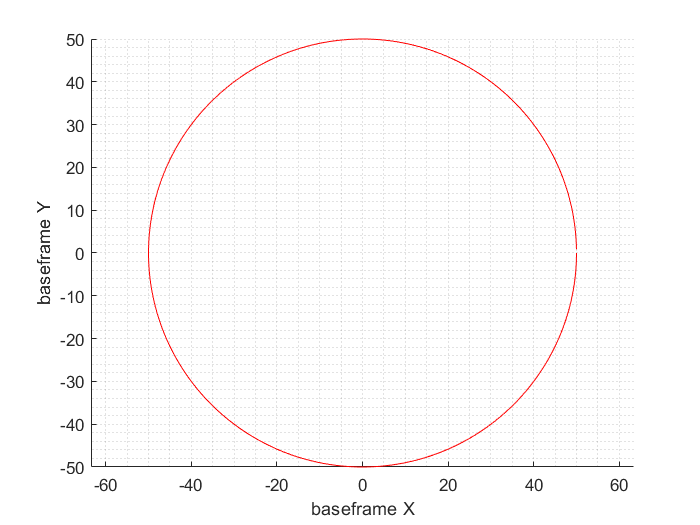



figure(4)
clf
hold on;
ij_range = 1:size(sli,1); %1:24; %[1 2];
for i=ij_range %:size(sli_data_hexa_rot,2)
%     plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.','color',colors(i,:))
    %plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.b')
%     plot3(mean(sli_data_hexa_rot{i}.Q(1,:))/1000,mean(sli_data_hexa_rot{i}.Q(2,:))/1000,mean(sli_data_hexa_rot{i}.Q(3,:))/1000,'*','color',colors(i,:),'markersize',10)
end

grid minor;
%axis ij;
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")
x = [];
y = [];
z = [];
for i=1:size(sli_data_hexa_rot,2)
    x = [x sli_data_hexa_rot{i}.Q(1,:)/1000];
    y = [y sli_data_hexa_rot{i}.Q(2,:)/1000];
    z = [z sli_data_hexa_rot{i}.Q(3,:)/1000];
end
hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r, circ_y*circ_r, mean(z)*ones(size(circ_x)), 'r')

axis equal

%xlim([-50, 50])

O_sparse = [-4.97106199398101	-23.3166644021243	25.9323627986420];
    
unit_vec_sparse = ...
[-0.288747648637093	    0.306293242445162	0.907088333647269	19; ...
-0.158749579397549	    0.489889012839238	0.857209032932166	24; ...
-0.109768703619059	    0.203271681156385	0.972949872987117	27; ...
-0.0907968144078339	    0.0381900376058185	0.995136904913618	29; ...
-0.00567908914511474	0.521497048049676	0.853234186388448	30; ...
0.0207666893788740	    0.386062644452971	0.922238786416089	32; ...
0.0437189127391662	    0.236202180725793	0.970719932055217	34; ...
0.171328431220356	    0.404572093780863	0.898313970496586	38; ...
0.193597326951717	    0.255385818084361	0.947258232436400	40; ...
0.360415150717705	    0.0970278401199079	0.927731921071384	48; ...
-0.132920541223632	    0.353306930817220	0.926016383417341	153; ...
0.0622579867034057	    0.0721187237278580	0.995451070007714	165; ...
0.319234128656939	    0.411526809366900	0.853659918394289	170; ...
0.212495249872407	    0.0913461994675134	0.972883158773192	171; ...
0.341601505721431	    0.261113540324678	0.902844466310762	173];

        unit_vec_sparse = [...
       -0.2887    0.3063    0.9071   19.0000;... %
   -0.1587    0.4899    0.8572   24.0000;... %
   -0.1098    0.2033    0.9729   27.0000;... %
   -0.0908    0.0382    0.9951   29.0000;... %
   -0.0057    0.5215    0.8532   30.0000;... %
    0.0208    0.3861    0.9222   32.0000;... %
    0.0437    0.2362    0.9707   34.0000;... %
    0.1713    0.4046    0.8983   38.0000;... %
    0.1936    0.2554    0.9473   40.0000;... %
    0.3604    0.0970    0.9277   48.0000;... %
   -0.2652    0.1546    0.9517  148.0000;... %
   -0.2459   -0.0112    0.9692  149.0000;... %
   -0.1329    0.3533    0.9260  153.0000;... %
    0.0623    0.0721    0.9955  165.0000;... %
    0.3192    0.4115    0.8537  170.0000;... %
    0.2125    0.0913    0.9729  171.0000;... %
    0.3416    0.2611    0.9028  173.0000]; %

dist2plane = 65; draw = 0;
[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);

%clf
%figure(6)


rot_xy = [];
rot_sparseQ = [];
for j = ij_range %1:length(hexa_pos)%29%1:30
    
    % Translation matrix

    %T = [1, 0, 0, pivot_point(1); 0, 1, 0, pivot_point(2); 0, 0, 1, pivot_point(3); 0, 0, 0, 1];

    % Rotation to align with base-frame
    best_angle_x = 18;%18.27;
    best_angle_y = 0;%-0.38;
    best_angle_z = 0;%0.2700;
        
    pivot_point_ = 190; %mm
    c2x_y = 23;        %mm
    c2x_y = 19.0365; % 18.9053;
    x2c_z = 22997*1e-3; %mm
    %x2c_z = 27.6692; % 27.7592;   
    desired_distance = 30; %mm
    

    Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
    Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    R = createRotationMatrix(hexa_pos(6,j),hexa_pos(5,j),hexa_pos(4,j));
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    %T_rot = [1, 0, 0, hexa_pos(1, j); 0, 1, 0, hexa_pos(2, j); 0, 0, 1, hexa_pos(3, j); 0, 0, 0, 1];
    %T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    %T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray(3); 0, 0, 0, 1];
    %pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    % c2x_y = 23%*10^3;        %um
    % x2c_z = 22.997;          %um
    %T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
    T_pivot = [1, 0, 0, 0; 0, 1, 0, c2x_y; 0, 0, 1, (pivot_point_-desired_distance-x2c_z); 0, 0, 0, 1];
    T_ = [1, 0, 0, hexa_pos(1, j)./1e3; 0, 1, 0, hexa_pos(2, j)./1e3; 0, 0, 1, hexa_pos(3, j)./1e3; 0, 0, 0, 1];
    
    %RT = R*T_rot*Rc*T_pivot^-1;
    
    %RT = T_pivot*R*T_pivot^-1*T_base^-1*T_p2*Rc*T_p2^-1;
    RT = T_*R'*T_pivot*Rc;
    
    pos_rot = RT*[target_cen, 1]';
    pos_rot = pos_rot(1:3)';
    
    % Finding the delta-x-y coordinates of the rotations
    
    O_sparse_SLI = RT*[O_sparse, 1]';
    O_sparse_SLI = O_sparse_SLI(1:3)';
    
    sparseQ_coor = sparseQ(sparseQ(:, 5) == j, :);
    for k = 1:size(sparseQ_coor, 1)
        sparseQ_r = RT*[sparseQ_coor(k, 1:3), 1]';
        sparseQ_(k, 1:3) = sparseQ_r(1:3)';
        rsQ(k, :) = [sparseQ_(k, 1:3), sparseQ_coor(k, 4:5)];
        %rsQ_ = (sparseQ_(k, 1:3) - O_sparse_SLI)./norm(sparseQ_(k, 1:3) - O_sparse_SLI);
        %[rsQ_, ~] = line_plane_intersection(rsQ_, O_sparse_SLI, [0, 0, 1], target_cen);
        %rsQ(k, :) = [rsQ_, sparseQ_coor(k, 4:5)];
    end
    
    rot_sparseQ = [rot_sparseQ; rsQ];
    
end

I_apriori = [];
for i = ij_range %1:size(hexa_pos, 2)
    I_sparse = reprojectSLI(O_sparse, unit_vec_sparse, p2, h_xray, pivot_point, target_cen, hexa_pos(4:6, i)', [0, 0, 0], 0);
    I_apriori = [I_apriori; [[I_sparse, i*ones(size(I_sparse, 1), 1)]]];
end

TargetCircle = drawCircle(50, [0, 0, mean(I_apriori(:, 3))], [0, 0, 1],'r', 2);



figure(505)
clf

hold on
%plot3(-rot_sparseQ(:, 1)  - 136, -rot_sparseQ(:, 2) + 131, rot_sparseQ(:, 3), 'g.')

view(0,90)
%axis equal
%xlim([-50, 50])
%ylim([-50, 50])

xlim([-136-60, -136+60])
ylim([131-60, 131+60])
%legend('Prediction', 'Processed data')

T = readtable('C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\NASA_DATA_TO_COMPARE.xlsx');

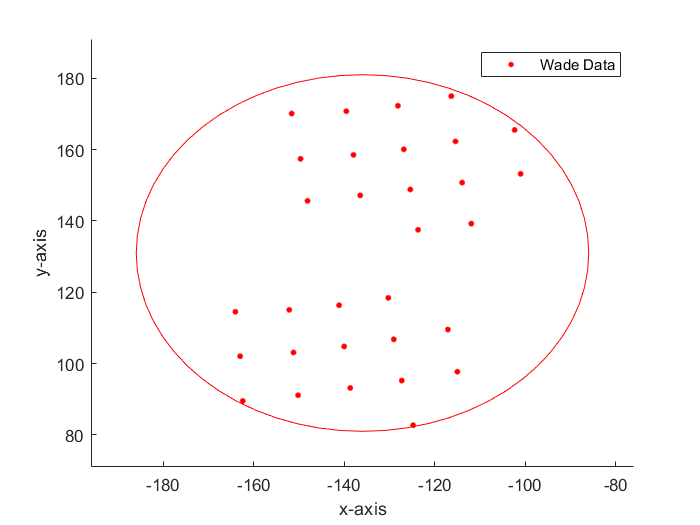

X = T.X*1000;
Y = T.Y*1000;
Z = T.Z*1000;
Tgt_X = T.Tgt_X(~isnan(T.Tgt_X))*1000;
Tgt_X = Tgt_X(2:end);
Tgt_Y = T.Tgt_Y(~isnan(T.Tgt_Y))*1000;
Tgt_Y = Tgt_Y(2:end);

% plot3(-0.97*(X + 121.1115) - 12, -0.97*(Y - 151.54716) - 28, Z, 'r.', 'MarkerSize', 7)
%plot3(-1*(X + 121.1115) - 14.5, -1*(Y - 151.54716) - 30, Z, 'r.', 'MarkerSize', 7)
scale = 1;
plot3(X(ismember(T.ScanPt, [11, 26])), Y(ismember(T.ScanPt, [11, 26])), Z(ismember(T.ScanPt, [11, 26])), 'r.', 'MarkerSize', 10)
%plot3(-rot_sparseQ(:, 1)  - 136, -rot_sparseQ(:, 2) + 131, rot_sparseQ(:, 3), 'g.')

% plot3(-I_apriori(ismember(I_apriori(:, 5), [11, 26]), 1) - 136,... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
%       -I_apriori(ismember(I_apriori(:, 5), [11, 26]), 2) + 131,...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
%       I_apriori(ismember(I_apriori(:, 5), [11, 26]), 3), 'b.', 'LineWidth', 1.5, 'MarkerSize', 10) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))

view(0, 90)
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
plot3(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, TargetCircle(:, 3), 'r-')

legend('Wade Data')

figure(506)
clf

hold on
%plot3(-rot_sparseQ(:, 1)  - 136, -rot_sparseQ(:, 2) + 131, rot_sparseQ(:, 3), 'g.')

view(0,90)
%axis equal
%xlim([-50, 50])
%ylim([-50, 50])

xlim([-136-60, -136+60])
ylim([131-60, 131+60])
%legend('Prediction', 'Processed data')

T = readtable('C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\NASA_DATA_TO_COMPARE.xlsx');

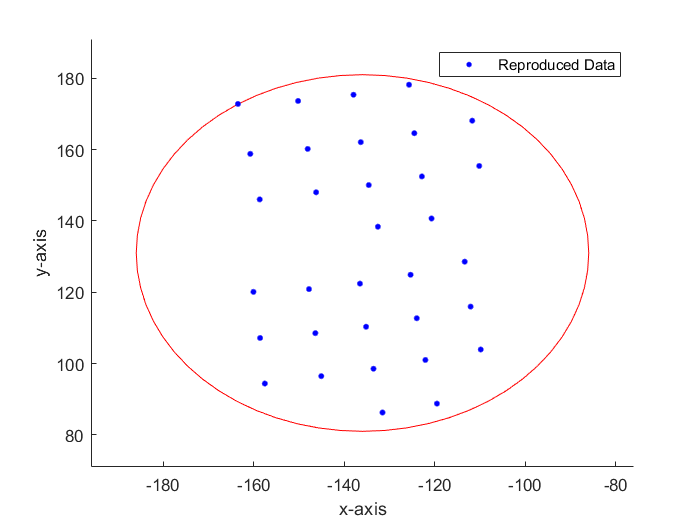

X = T.X*1000;
Y = T.Y*1000;
Z = T.Z*1000;
Tgt_X = T.Tgt_X(~isnan(T.Tgt_X))*1000;
Tgt_X = Tgt_X(2:end);
Tgt_Y = T.Tgt_Y(~isnan(T.Tgt_Y))*1000;
Tgt_Y = Tgt_Y(2:end);

% plot3(-0.97*(X + 121.1115) - 12, -0.97*(Y - 151.54716) - 28, Z, 'r.', 'MarkerSize', 7)
%plot3(-1*(X + 121.1115) - 14.5, -1*(Y - 151.54716) - 30, Z, 'r.', 'MarkerSize', 7)
scale = 1;
%plot3(X(ismember(T.ScanPt, [11, 26])), Y(ismember(T.ScanPt, [11, 26])), Z(ismember(T.ScanPt, [11, 26])), 'r.', 'MarkerSize', 10)
%plot3(-rot_sparseQ(:, 1)  - 136, -rot_sparseQ(:, 2) + 131, rot_sparseQ(:, 3), 'g.')

plot3(-I_apriori(ismember(I_apriori(:, 5), [11, 26]), 1) - 136,... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
      -I_apriori(ismember(I_apriori(:, 5), [11, 26]), 2) + 131,...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
      I_apriori(ismember(I_apriori(:, 5), [11, 26]), 3), 'b.', 'LineWidth', 1.5, 'MarkerSize', 10) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))

view(0, 90)
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
plot3(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, TargetCircle(:, 3), 'r-')

legend('Reproduced Data')

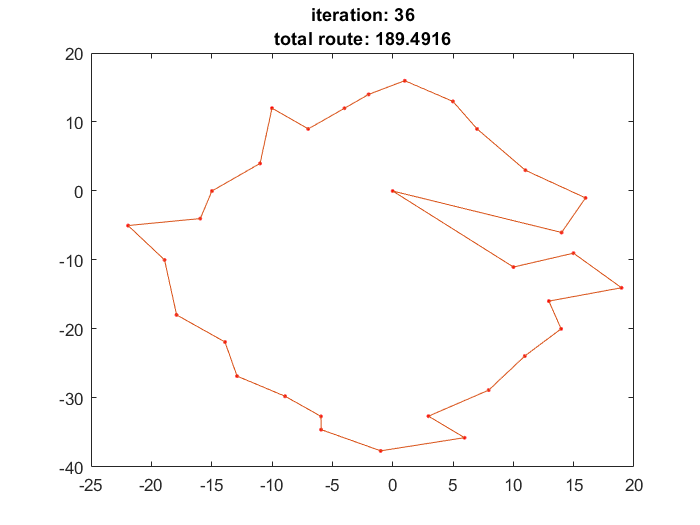

dist2plane = 65;
[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);

rot_selected = hexa_pos(4:6, :)'; % rot_opt_22; % rot_24_first; %% AND BEST!

pos_xy = [];
for s = 1:size(rot_selected, 1)
    [R, Rc] = deal([]);
    R = createRotationMatrix(-rot_selected(s, 3), -rot_selected(s, 2), -rot_selected(s, 1));
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    % Rotation to align with base-frame
    best_angle_x = 18; % 18.27; % 18
    best_angle_y = 0; % -0.38; % 0
    best_angle_z = 0; % 0.2700; % 0
    Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
    Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];
    pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
                    
    RT = T_pivot*R*T_pivot^-1*T_base^-1*T_p2*Rc*T_p2^-1;  
    target_cen_rot = T_base^-1*T_p2*Rc*T_p2^-1*[target_cen, 1]';
    target_cen_rot = target_cen_rot(1:3)';
    
    p_xray_rot = RT*[p_xray, 1]';
    p_xray_rot = p_xray_rot(1:3)';
    
    Nref_rot = R*Rc*[Nref, 1]';
    Nref_rot = Nref_rot(1:3)'; 
    
    % Find out where the rotated unit vectors intersect with the plane
    [pos_xy(s, :), ~] = line_plane_intersection(Nref_rot, p_xray_rot, [0, 0, 1], target_cen_rot); % target_cen_rot + [+0.5618, +0.4032, -40.7507]
end
%size(pos_xy)

clf
%prompt = "How many pictures would you like to use? ";
n_pictures = length(pos_xy); %size(rot_opt, 1);
%n_pictures = input(prompt);

[sortedCoords, sortedCoords_ID, ~] = solveTSP([-pos_xy(1:n_pictures, 1:2); [0, 0]], true);


sortedCoords = flip(sortedCoords(1:end-1, :))

sortedCoords =    13.9982   -6.0103
   15.9826   -1.0012
   15.9826   -1.0012
   10.9988    3.0031
    6.9949    8.9975
    4.9934   12.9859
    0.9993   15.9875
   -1.9991   13.9949
   -3.9950   11.9876
   -6.9985    9.0024


sortedCoords_ID = flip(sortedCoords_ID(1:end-1, :))

sortedCoords_ID =     31
    32
    33
    30
    29
    28
    27
    26
    25
    23


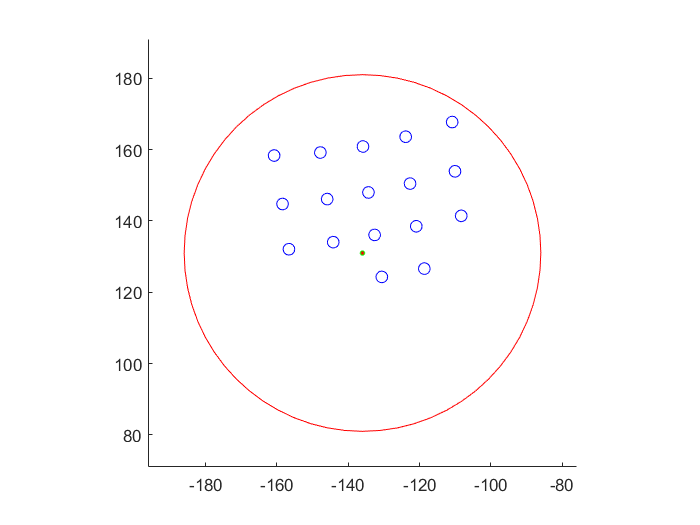

figure(111)
clf
hold on
for i=1:size(sli_data_hexa_rot,2)
    figure(111)
    clf
    hold on
    plot(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, 'r-')
    %plot(X(T.ScanPt == i), Y(T.ScanPt == i), 'r.', 'MarkerSize', 7)
    plot(-pos_xy(i, 1) - 136, -pos_xy(i, 2) + 131, 'g.-', 'MarkerSize', 10)
    plot(Tgt_X(i), Tgt_Y(i), 'r.-', 'MarkerSize', 5)
    plot(-I_apriori(I_apriori(:, 5) == i, 1) - 136,... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
      -I_apriori(I_apriori(:, 5) == i, 2) + 131,...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
      'bo', 'MarkerSize', 7) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))
    axis equal
    
    xlim([-136-60, -136+60])
    ylim([131-60, 131+60])
    %waitforbuttonpress
end

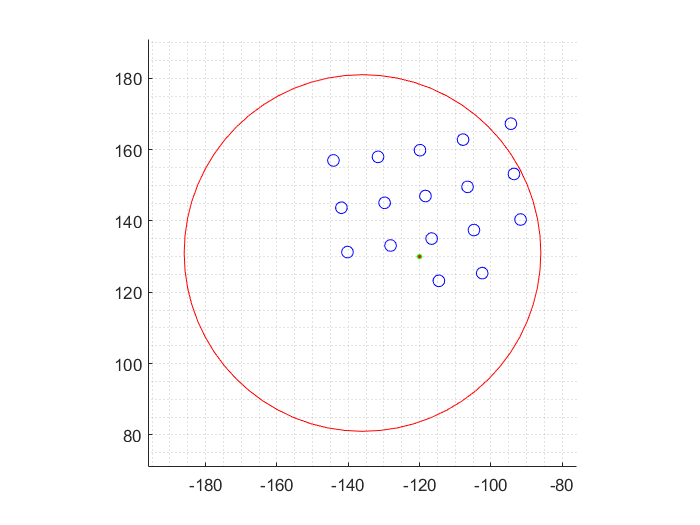

grid minor;

% clf
% %figure(105)
% set(0,'DefaultFigureWindowStyle','docked')
% set(gca,'FontSize',14)
% set(gca,'LineWidth',1)
% set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
% set(gcf, 'PaperPositionMode', 'auto')
% title('X-ray scan pattern trace','interpreter','latex', 'FontSize', 15)
% xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
% ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
% filename = 'SLI_and_Xray_Wade_mean.gif';

hold on

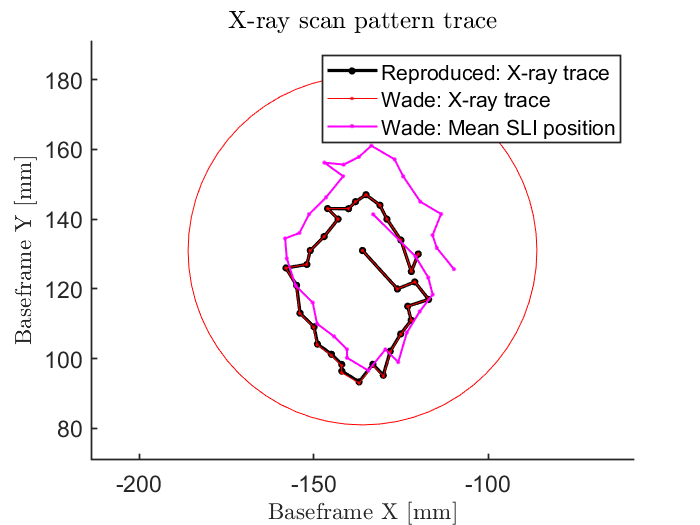


I_apriori_mean = zeros(size(sli, 1), 2);
for j = 1:size(sli, 1)
    I_apriori_mean(j, 1) = mean(-I_apriori(ismember(I_apriori(:, 5), j), 1) - 136);
    I_apriori_mean(j, 2) = mean(-I_apriori(ismember(I_apriori(:, 5), j), 2) + 131);
end

XY_mean = zeros(size(sli, 1), 2);
for j = 1:size(sli, 1)
    XY_mean(j, 1) = mean(X(T.ScanPt == j));
    XY_mean(j, 2) = mean(Y(T.ScanPt == j));
end

%subplot(2,2,1)
figure(234)
clf
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('X-ray scan pattern trace','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)

hold on
plot(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, 'r-')
plot(-pos_xy(:, 1) - 136, -pos_xy(:, 2) + 131, 'k.-', 'MarkerSize', 15, 'LineWidth', 2)
plot(Tgt_X(:), Tgt_Y(:), 'r.-', 'MarkerSize', 5, 'LineWidth', .4)
    
plot(XY_mean(:, 1), XY_mean(:, 2), 'm.-', 'MarkerSize', 7, 'LineWidth', 1.2)


xlim([-136-60, -136+60])
ylim([131-60, 131+60])
legend('', 'Reproduced: X-ray trace', 'Wade: X-ray trace', 'Wade: Mean SLI position')
axis equal

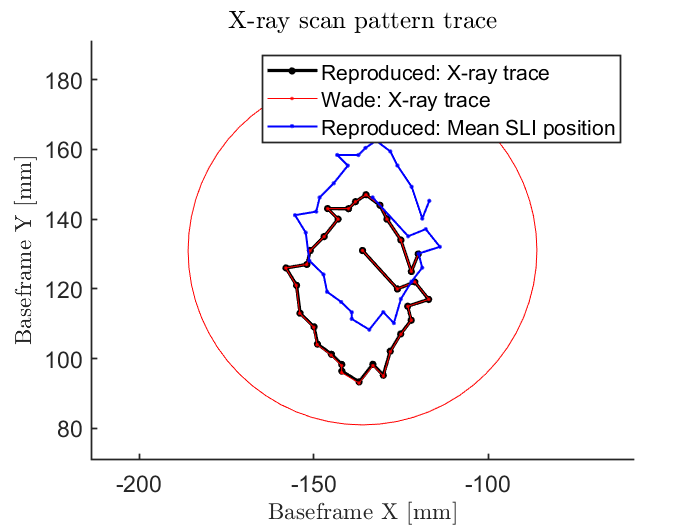


%subplot(2,2,2)
figure(567)
clf
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('X-ray scan pattern trace','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)

hold on
plot(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, 'r-')
plot(-pos_xy(:, 1) - 136, -pos_xy(:, 2) + 131, 'k.-', 'MarkerSize', 15, 'LineWidth', 2)
plot(Tgt_X(:), Tgt_Y(:), 'r.-', 'MarkerSize', 5, 'LineWidth', .4)
    
plot(I_apriori_mean(:, 1),... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
  I_apriori_mean(:, 2),...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
  'b.-', 'MarkerSize', 7, 'LineWidth', 1.2) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))
  

xlim([-136-60, -136+60])
ylim([131-60, 131+60])
legend('', 'Reproduced: X-ray trace', 'Wade: X-ray trace', 'Reproduced: Mean SLI position')
axis equal

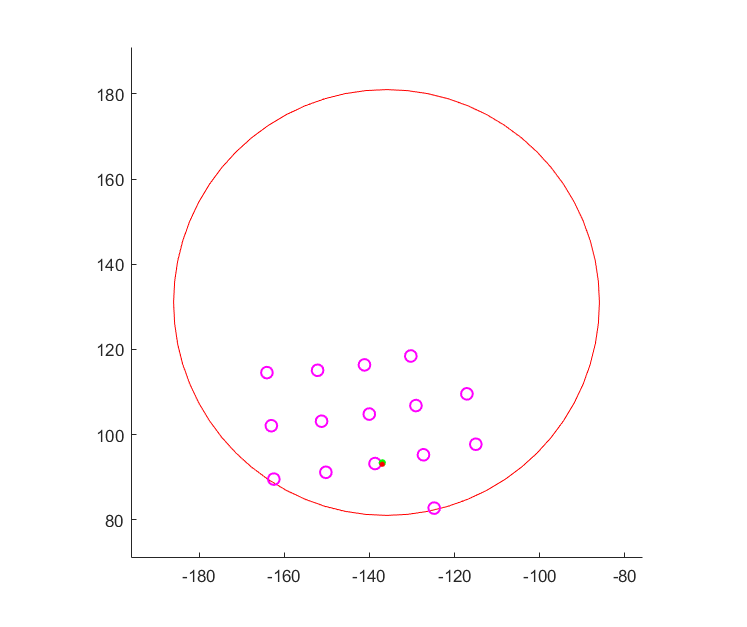

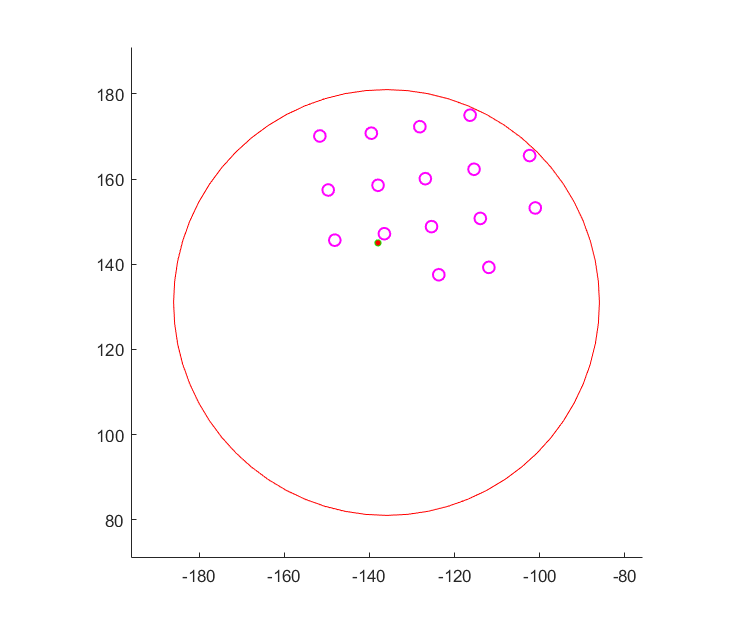

clf
figure(105)
clf
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('X-ray scan pattern trace','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
filename = 'SLI_and_Xray_Wade_10_11.gif';

for i = [11 11 11 11 11 11 26 26 26 26 26 26] %10:11 %1:size(sli, 1)
    figure(105)
    clf
    hold on
    plot(TargetCircle(:, 1) - 136, TargetCircle(:, 2) + 131, 'r-')
    plot(X(T.ScanPt == i), Y(T.ScanPt == i), 'mo', 'MarkerSize', 7, 'LineWidth', 1.2)
    %plot(XY_mean(1:i, 1), XY_mean(1:i, 2), 'g.-', 'MarkerSize', 7, 'LineWidth', 1.2)
    
    
    plot(-pos_xy(i, 1) - 136, -pos_xy(i, 2) + 131, 'g.-', 'MarkerSize', 15)
    plot(Tgt_X(i), Tgt_Y(i), 'r.-', 'MarkerSize', 10)
%     plot(-I_apriori(I_apriori(:, 5) == i, 1) - 136,... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
%       -I_apriori(I_apriori(:, 5) == i, 2) + 131,...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
%       'bo', 'MarkerSize', 7, 'LineWidth', 1.2) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))
% 

% Mean SLI point values
%     plot(I_apriori_mean(1:i, 1),... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
%       I_apriori_mean(1:i, 2),...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
%       'b.-', 'MarkerSize', 7, 'LineWidth', 1.2) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))
%    
    axis equal
    
    xlim([-136-60, -136+60])
    ylim([131-60, 131+60])
    
    drawnow
    frame = getframe;
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,128);
    if i == 11;
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
end

clf
figure(5)
T = readtable('C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\NASA_DATA_TO_COMPARE.xlsx');

X = T.X*1000;
Y = T.Y*1000;
Z = T.Z*1000;
Tgt_X = T.Tgt_X(~isnan(T.Tgt_X))*1000;
Tgt_X = Tgt_X(2:end);
Tgt_Y = T.Tgt_Y(~isnan(T.Tgt_Y))*1000;
Tgt_Y = Tgt_Y(2:end);

%  Tgt-X'   Tgt_Y' -0,136 [m]	0,123 [m]


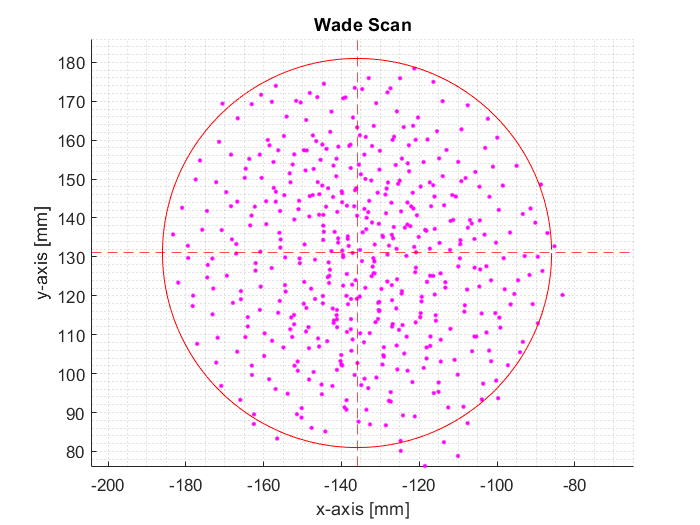

figure(801)
clf
center_point = [-136, 131];
hold on

xline(center_point(1), 'r--')
yline(center_point(2), 'r--')
plot(X, Y, 'm.', 'MarkerSize', 7)
view(0, 90)
xlabel('x-axis [mm]')
ylabel('y-axis [mm]')
zlabel('z-axis [mm]')
%axis ij
hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r - 136, circ_y*circ_r + 131, mean(Z)*ones(size(circ_x)), 'r-')
title('Wade Scan')

grid minor
xlim([center_point(1) - 55, center_point(1) + 55])
ylim([center_point(2) - 55, center_point(2) + 55])
axis equal

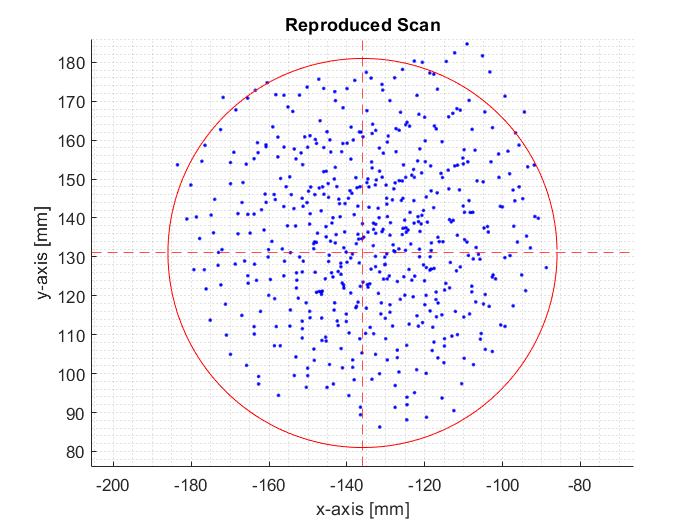

figure(802)
clf
%center_point = -[-136, 131];
hold on

xline(center_point(1), 'r--')
yline(center_point(2), 'r--')
plot(-I_apriori(:, 1) - 136,... % - mean(I_apriori(:, 1)) + mean(rot_sparseQ(:, 1)) + 3.61372 - 0.57671
      -I_apriori(:, 2) + 131,...  % + 3   %  - mean(I_apriori(:, 2)) + mean(rot_sparseQ(:, 2)) + 3.3303 - 1.3719
       'b.', 'LineWidth', 1.5) %  - mean(I_apriori(:, 3)) + mean(rot_sparseQ(:, 3))
view(0, 90)
xlabel('x-axis [mm]')
ylabel('y-axis [mm]')
zlabel('z-axis [mm]')
%axis ij
hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r - 136, circ_y*circ_r + 131, mean(Z)*ones(size(circ_x)), 'r-')
title('Reproduced Scan')

grid minor
xlim([center_point(1) - 55, center_point(1) + 55])
ylim([center_point(2) - 55, center_point(2) + 55])
axis equal